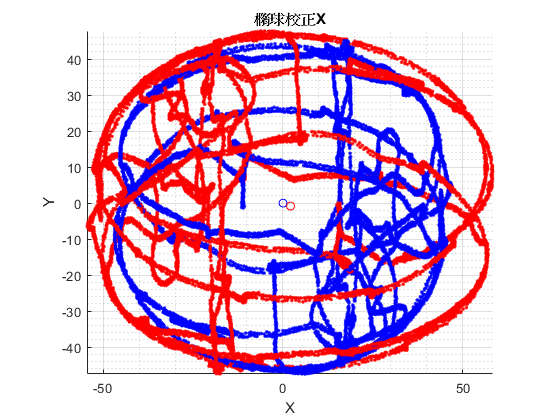

clear; close all;


% fitdata=xlsread('fit data\11 26 new fit data 2mag new place_th_2.8_m2濾y.xlsx');
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');
Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

% 時間  加速度(m/s/s)XYZ 角速度XYZ 磁力XYZ 放在data.txt 中
% data=load('fitdata\11 26 new fit code 2mag new place grass.csv');
data=load('fit data\fitdata16475.csv');

acc=data(:,2:4);
gyr=data(:,5:7);
mag=data(:,8:10);
mag2=data(:,11:13);
Aa=sqrt(acc(:,1).^2+acc(:,2).^2+acc(:,3).^2);
Ag=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2);
Am=sqrt(mag(:,1).^2+mag(:,2).^2+mag(:,3).^2);
Am2=sqrt(mag2(:,1).^2+mag2(:,2).^2+mag2(:,3).^2);


[a1 a2]=size(data);
data_corr=zeros(a1,a2);
data_corr(:,1)=data(:,1);
for i=1:a1   %校正數據
    data_corr(i,2:4)=(Ta*Ka*(data(i,2:4)'+Ba))';
    data_corr(i,5:7)=(Tg*Kg*(data(i,5:7)'+Bg))';
    data_corr(i,8:10)=(Tm2a*(data(i,8:10)'+Bm))';
    data_corr(i,11:13)=(Tm2a_2*(data(i,11:13)'+Bm_2))';
end
X=data(:,8:10);
Xnew=data_corr(:,8:10);
Xneww=sqrt(Xnew(:,1).^2+Xnew(:,2).^2+Xnew(:,3).^2);
Xw=sqrt(X(:,1).^2+X(:,2).^2+X(:,3).^2);
X2=data(:,11:13);
Xnew2=data_corr(:,11:13);
Xneww2=sqrt(Xnew2(:,1).^2+Xnew2(:,2).^2+Xnew2(:,3).^2);
Xw2=sqrt(X2(:,1).^2+X2(:,2).^2+X2(:,3).^2);

close all
figure(1)
hold on

scatter3(X(:,1),X(:,2),X(:,3),'red.')
scatter3(Xnew(:,1),Xnew(:,2),Xnew(:,3),'blue.')
scatter3(Bm(1)*-1,Bm(2)*-1,Bm(3)*-1,'ro')
scatter3(0,0,0,'blueo')

title('橢球校正X')
grid on
grid minor
axis equal tight
xlabel('X');
ylabel('Y');
zlabel('Z');
hold off

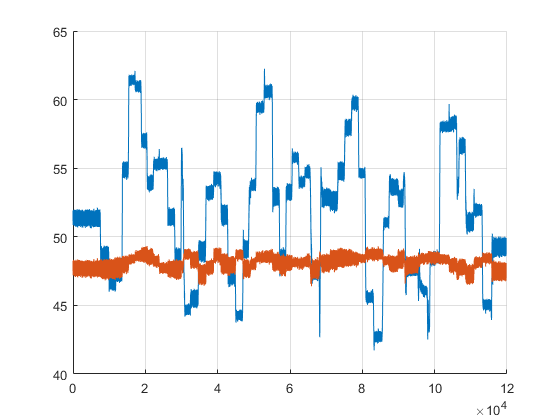

%
figure(2)
hold on
plot(Xw)
plot(Xneww)
grid on
hold off

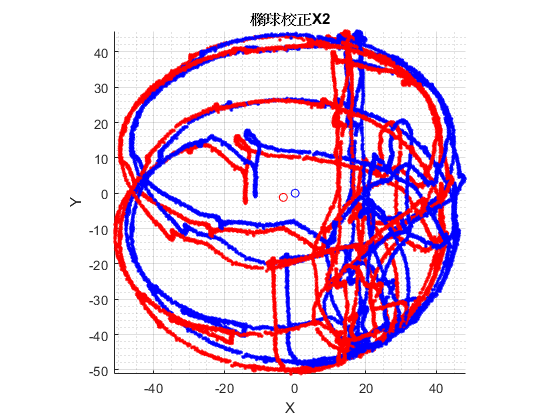


figure(3)
hold on
%
scatter3(X2(:,1),X2(:,2),X2(:,3),'red.')
scatter3(Xnew2(:,1),Xnew2(:,2),Xnew2(:,3),'blue.')
scatter3(Bm_2(1)*-1,Bm_2(2)*-1,Bm_2(3)*-1,'ro')
scatter3(0,0,0,'blueo')
%
title('橢球校正X2')
grid on
grid minor
axis equal tight
xlabel('X');
ylabel('Y');
zlabel('Z');
hold off

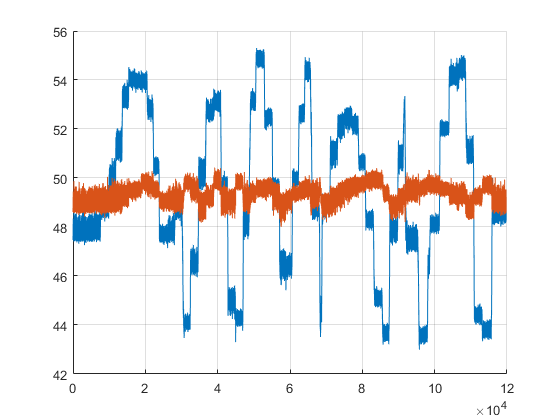

%
figure(4)
hold on
plot(Xw2)
plot(Xneww2)
grid on
hold off

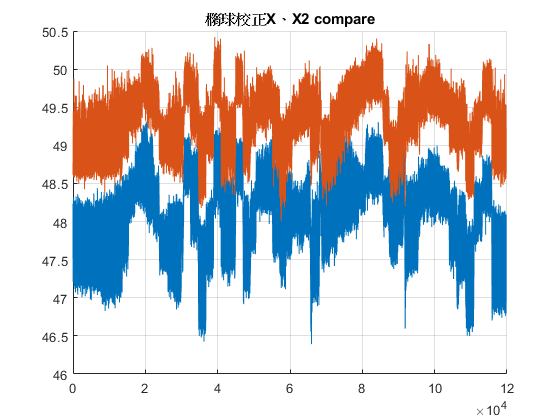


figure(5)
hold on
plot(Xneww)
plot(Xneww2)
grid on
title('橢球校正X、X2 compare')
hold off

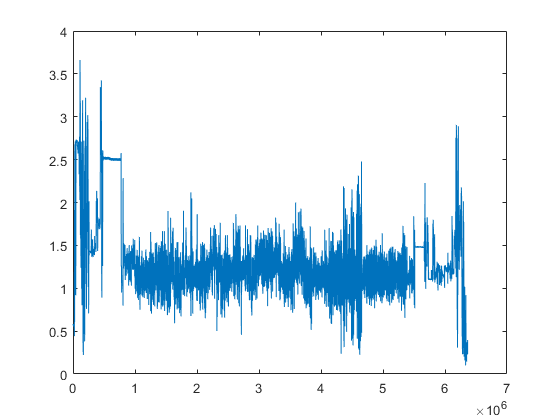

%% Corr_Mag
clear all;close all;
% fitdata=xlsread('fit data\11 26 new fit data 2mag new place_th_2.8_m2濾y.xlsx');
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');

Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

close all

% mo1=load('proj\5 25 26 羅森實測\5 25\log231.csv');
% mo2=load('proj\5 25 26 羅森實測\5 25\log232.csv');
% mo3=load('proj\5 25 26 羅森實測\5 25\log233.csv');
% mo4=load('proj\5 25 26 羅森實測\5 25\log234.csv');
% mo5=load('proj\5 25 26 羅森實測\5 25\log235.csv');
% mo6=load('proj\5 25 26 羅森實測\5 25\log236.csv');

mo1=load('proj\5 25 26 羅森實測\5 26\log253.csv');
mo2=load('proj\5 25 26 羅森實測\5 26\log254.csv');
mo3=load('proj\5 25 26 羅森實測\5 26\log255.csv');
mo4=load('proj\5 25 26 羅森實測\5 26\log256.csv');
mo5=load('proj\5 25 26 羅森實測\5 26\log257.csv');

%  mo=load('C:\Users\henry chen\Desktop\temp\log262.csv');
%  moo=mo;

% moo=[mo1;mo2;mo3;mo4;mo5;mo6];   %5 25
moo=[mo1;mo2;mo3;mo4;mo5];    %5 26

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);

% mo=moo(:,[1:4,8:16]);
mo=moo(:,[1:13]);  %%%%%%%%%%%%%%%%16475%%%%%%%%%%%%%%%%%%
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency 
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,8:10)*0.01; %%%% to guess
m2 = mo(:,11:13)*0.01; %%%%

ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
% ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
% aG2o=sqrt(mo_cor(:,5).^2+mo_cor(:,6).^2+mo_cor(:,7).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
% aG2=sqrt(ax2.^2+ay2.^2+az2.^2);

GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;

mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);

stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

plot(mm42)

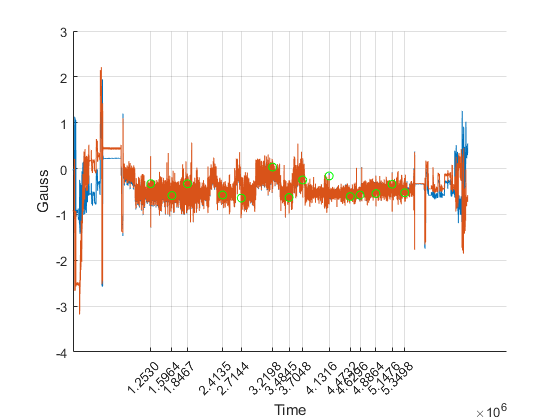

%% 定位AGM資料點
% hour1=10;mins1=09;secs1=00; %5 25 IP 時間點
% hour=[11 11 12 12 12 12 12 13 13 13 13 14];
% mins=[40 56 05 14 22 37 50 04 16 28 47 47];
% secs=[31 00 06 07 26 57 43 58 35 07 35 09];

hour1=15; mins1=29; secs1=30; %5 26 IP 時間點
hour=[16 16 16 17 17 17 18 18 18 18 18 19 19 19];
mins=[23 38 49 14 27 49 01 10 29 44 51 02 13 22];
secs=[32 55 34 08 26 54 12 43 25 39 42 46 58 44];


[~,k]=size(mins);
on=[];
for i=1:k
    on(i)=hour(i)*60*60+mins(i)*60+secs(i);
end
on1=hour1*60*60+mins1*60+secs1;

% on=on-on1+t(6860);  %5 25
on=on-on1+t(10000);  %5 26

[~,k]=size(on);
ed=[];
eds=[];
ton=[];
toff=[];
ed(k,:)=0;
eds(k,3)=0;
ton(k,:)=0;
toff(k,:)=0;

for i=1:k
    [~,ton(i)]=min(abs(t-on(i)));
end
ticks=[ton];
ticks=reshape (ticks, 1, numel(ticks));
ticks=sort(ticks,'ascend');


close all
hold on
plot(m(:,1))
% plot(m2(:,1)*-1-0.35)  %25
plot(m2(:,1)*-1-0.9)  %26
% plot(m2(:,1)*1+0.28)  %25   %校正後兩磁力儀方向一樣?
% plot(m2(:,1)*1+0.72)  %26   %校正後兩磁力儀方向一樣?
% plot(m2(:,1))
% plot(m)
tickson=[ton];
tickson=reshape (tickson, 1, numel(tickson));
tickson=sort(tickson,'ascend');

for i=1:k
    plot(tickson(i),m(tickson(i),1),'go')
end
set(gca, 'xtick', ticks);
grid on
xlabel('Time')
ylabel('Gauss')
hold off

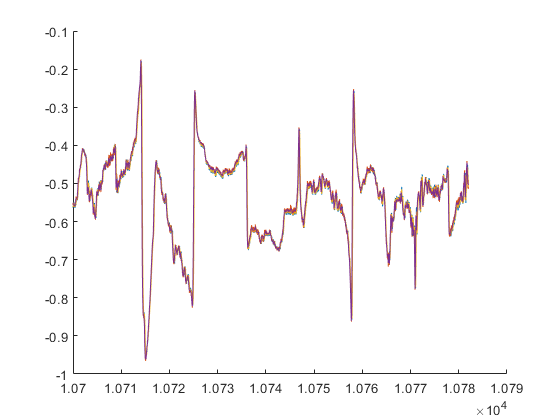








fs=400; %frequency rate
fc = 7; %for startn finding
fc = 9; %for find peak difference fly
% fc = 90; %for find peak difference fly
[b,a] = butter(2,fc/(fs/2),'low'); % Butterworth filter of order 6
sm=filtfilt(b, a, m);
sm2=filtfilt(b, a, m2);

figure(2) %7 23 find 過河道速度
hold on
rangee=[10700 10782];
for i=1:2
    [~,rangeee(i)]=min(abs(t-rangee(i)));
end
plot(t(rangeee(1):rangeee(2)),m((rangeee(1):rangeee(2)),1))
plot(t(rangeee(1):rangeee(2)),m2((rangeee(1):rangeee(2)),1)*-1-0.9)  %26

plot(t(rangeee(1):rangeee(2)),sm((rangeee(1):rangeee(2)),1))
plot(t(rangeee(1):rangeee(2)),sm2((rangeee(1):rangeee(2)),1)*-1-0.9)  %26
hold off

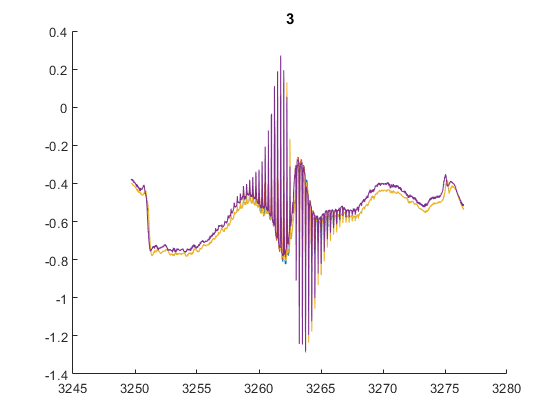

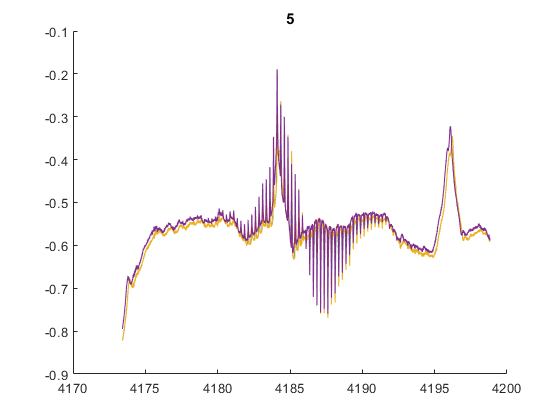

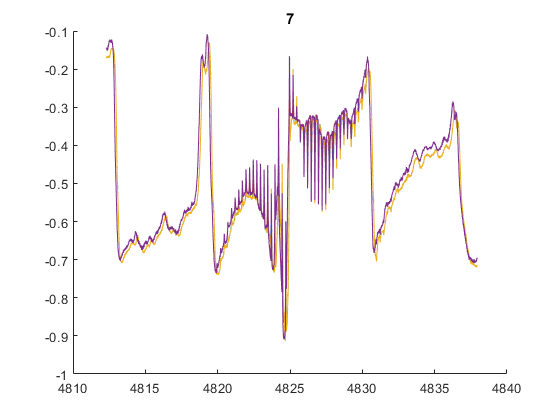

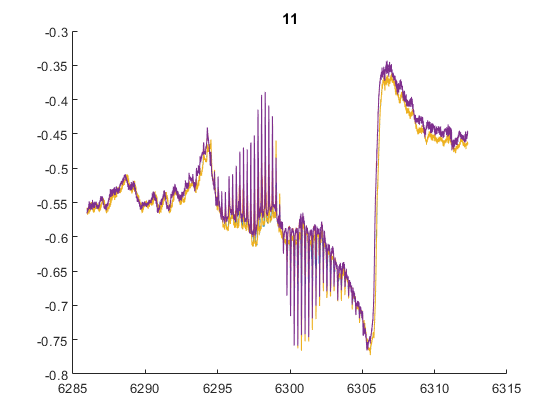

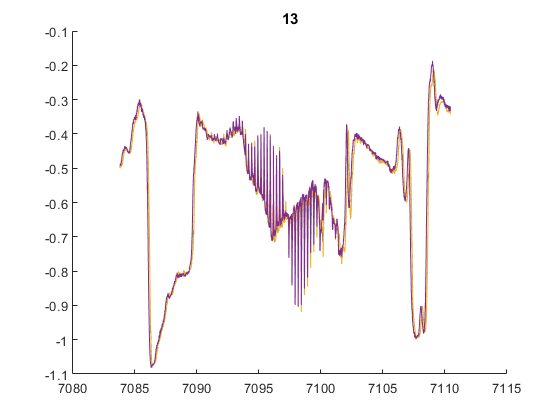

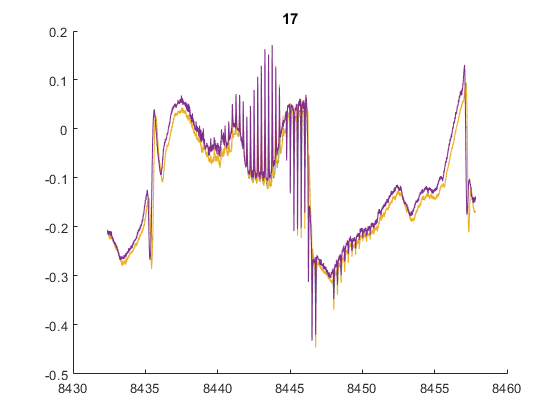

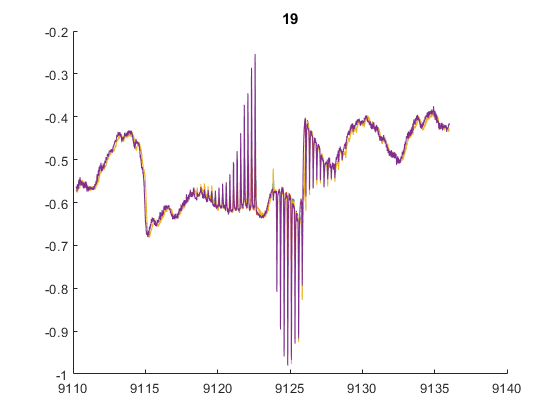

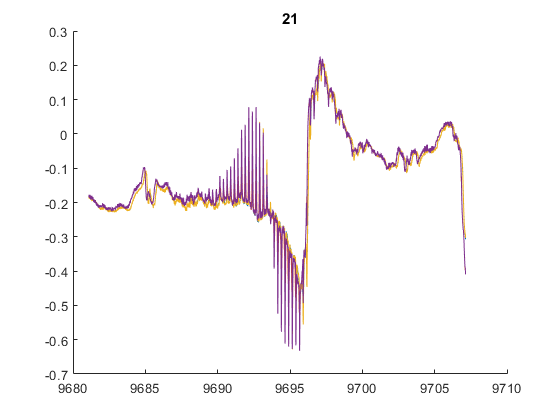

%% 取出AGM磁力區間
close all;
plus=400*25;  %設區間為25秒
% agm=[2 4 6 7 8 10 13 16 18 20 24 36];  %5 25
agm=[3 5 7 11 13 17 19 21 24 27 29 31 33 35];  %5 26
axi=1;
% waveN=16; %計算的波數 16(25)
waveN=13; %計算的波數  19(26)
n=12; %取的startn
startn=[];
startn2=[];
startn(waveN,k)=0;

fs=400; %frequency rate
fc = 7; %for startn finding
fc = 9; %for find peak difference fly
% fc = 90; %for find peak difference fly
[b,a] = butter(2,fc/(fs/2),'low'); % Butterworth filter of order 6
sm=filtfilt(b, a, m);
sm2=filtfilt(b, a, m2);
for i=1:k
    figure(i)
    title(agm(i))
    hold on    
    
%     plot(m((tickson(i)-plus/2):(tickson(i)+plus/2),axi))      %% m
%                                                                                m2
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.32)   %25
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.9)   %26
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*1+0.28)   %25   %校正後兩磁力儀方向一樣?
%     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*1)   %26   %校正後兩磁力儀方向一樣?
    %     plot(plus/2,m(tickson(i),axis),'go')
    
    %     plot(smooth(m((tickson(i)-plus/2):(tickson(i)+plus/2),axi),30)) %平滑
%     plot(sm((tickson(i)-plus/2):(tickson(i)+plus/2),axi))
    
%          plot(m((tickson(i)-plus/2):(tickson(i)+plus/2),:)) %三軸  
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),:)*-1)
    
    %     plot(plus/2,m(tickson(i),:),'ko') %定位點
%     plot(plus/2,m(tickson(i),axi),'ko')
    
    
    
    % x axis = time
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),sm((tickson(i)-plus/2):(tickson(i)+plus/2),axi))
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),sm2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.9)
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),m((tickson(i)-plus/2):(tickson(i)+plus/2),axi))
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.9)
    
    
    %%startn finding
%     ff=-2;
%     testdata=sm((tickson(i)-plus/2*0.3):(tickson(i)+plus/2*0.3),axi); % 用來判斷的數據
%     IndMin=find(diff(sign(diff(testdata)))>0)+ff;  %獲得局部最小值的位置(可微調位置
%     IndMax=find(diff(sign(diff(testdata)))<0)+ff;  %獲得局部最大值的位置
%     
%     IndMin(waveN+1:size(IndMin))=[]; % 使同長度
%     IndMax(waveN+1:size(IndMax))=[];
%     
%        
%     for j=1:waveN
%         what=tickson(i)-plus/2*0.3+IndMin(j);
%         what2=what-tickson(i)+plus/2;
%         startn(j,i)=what2;
%         startn2(i)=startn(n,i);
%         
%         plot(startn(j,i),m(what,axi),'r^') % 標示在原數據
%         %     plot(IndMin(j)+plus/2-plus/2*0.3,m(tickson(i)-plus/2*0.3+IndMin(j),axi),'r^') % 標示在原數據
%         plot(IndMax(j)+plus/2-plus/2*0.3,m(tickson(i)-plus/2*0.3+IndMax(j),axi),'k*')
%     end
%     plot(startn2(i),m(startn2(i)+tickson(i)-plus/2,axi),'ko') % 標示在原數據
%     
%     ylabel('Gauss')
%     hold off
end

% startn2=startn2';


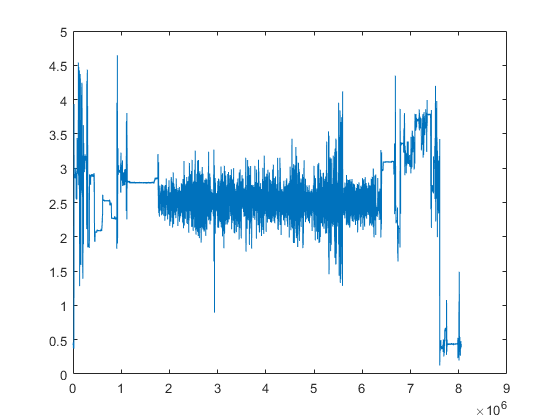


%% Corr_Mag
clear all;close all;
% fitdata=xlsread('fit data\11 26 new fit data 2mag new place_th_2.8_m2濾y.xlsx');
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');

Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

close all

mo1=load('proj\5 25 26 羅森實測\5 25\log231.csv');
mo2=load('proj\5 25 26 羅森實測\5 25\log232.csv');
mo3=load('proj\5 25 26 羅森實測\5 25\log233.csv');
mo4=load('proj\5 25 26 羅森實測\5 25\log234.csv');
mo5=load('proj\5 25 26 羅森實測\5 25\log235.csv');
mo6=load('proj\5 25 26 羅森實測\5 25\log236.csv');

% mo1=load('proj\5 25 26 羅森實測\5 26\log253.csv');
% mo2=load('proj\5 25 26 羅森實測\5 26\log254.csv');
% mo3=load('proj\5 25 26 羅森實測\5 26\log255.csv');
% mo4=load('proj\5 25 26 羅森實測\5 26\log256.csv');
% mo5=load('proj\5 25 26 羅森實測\5 26\log257.csv');

%  mo=load('C:\Users\henry chen\Desktop\temp\log262.csv');
%  moo=mo;

moo=[mo1;mo2;mo3;mo4;mo5;mo6];   %5 25
% moo=[mo1;mo2;mo3;mo4;mo5];    %5 26

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);

% mo=moo(:,[1:4,8:16]);
mo=moo(:,[1:13]); %%%%%%%%%%%%%%%%16475%%%%%%%%%%%%%%%%%%
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency 
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,8:10)*0.01; %%%% to guess
m2 = mo(:,11:13)*0.01; %%%%

ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
% ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
% aG2o=sqrt(mo_cor(:,5).^2+mo_cor(:,6).^2+mo_cor(:,7).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
% aG2=sqrt(ax2.^2+ay2.^2+az2.^2);

GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;

mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);

stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

plot(mm42)

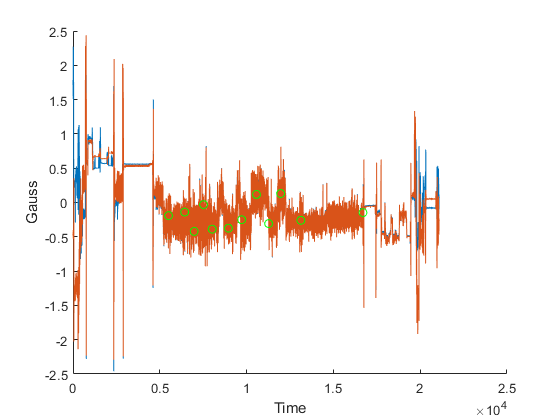

%% 定位AGM資料點
hour1=10;mins1=09;secs1=00; %5 25 IP 時間點
hour=[11 11 12 12 12 12 12 13 13 13 13 14];
mins=[40 56 05 14 22 37 50 04 16 28 47 47];
secs=[31 00 06 07 26 57 43 58 35 07 35 09];

% hour1=15; mins1=29; secs1=30; %5 26 IP 時間點
% hour=[16 16 16 17 17 17 18 18 18 18 18 19 19 19];
% mins=[23 38 49 14 27 49 01 10 29 44 51 02 13 22];
% secs=[32 55 34 08 26 54 12 43 25 39 42 46 58 44];


[~,k]=size(mins);
on=[];
for i=1:k
    on(i)=hour(i)*60*60+mins(i)*60+secs(i);
end
on1=hour1*60*60+mins1*60+secs1;

on=on-on1+t(6860);  %5 25
% on=on-on1+t(10000);  %5 26

[~,k]=size(on);
ed=[];
eds=[];
ton=[];
toff=[];
ed(k,:)=0;
eds(k,3)=0;
ton(k,:)=0;
toff(k,:)=0;

for i=1:k
    [~,ton(i)]=min(abs(t-on(i)));
end
ticks=[ton];
ticks=reshape (ticks, 1, numel(ticks));
ticks=sort(ticks,'ascend');


close all
hold on
plot(t,m(:,1))
plot(t,m2(:,1)*-1-0.33)  %25
% plot(t,m2(:,1)*-1-0.9)  %26
% plot(t,m2(:,1)*1+0.28)  %25   %校正後兩磁力儀方向一樣?
% plot(t,m2(:,1)*1+0.72)  %26   %校正後兩磁力儀方向一樣?
% plot(t,m2(:,1))
% plot(t,m)
tickson=[ton];
tickson=reshape (tickson, 1, numel(tickson));
tickson=sort(tickson,'ascend');

for i=1:k
%     plot(tickson(i),m(tickson(i),1),'go')
    plot(t(tickson(i)),m(tickson(i),1),'go')
end
% set(gca, 'xtick', ticks);
% grid on
xlabel('Time')
ylabel('Gauss')
hold off

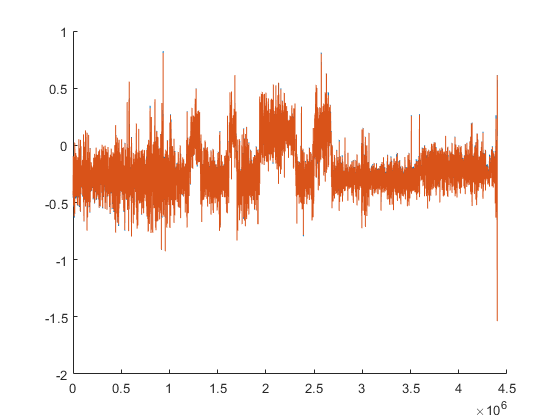







fs=400; %frequency rate
fc = 7; %for startn finding
fc = 9; %for find peak difference fly
% fc = 90; %for find peak difference fly
[b,a] = butter(2,fc/(fs/2),'low'); % Butterworth filter of order 6
sm=filtfilt(b, a, m);
sm2=filtfilt(b, a, m2);

figure(2) %7 23 find 過河道速度
hold on
% rangee=[13135 13223];
% rangee=[4909258 5069258];
rangee=[2000000 6400000];
for i=1:2
    [~,rangeee(i)]=min(abs(t-rangee(i)));
end
% plot(t(rangeee(1):rangeee(2)),m((rangeee(1):rangeee(2)),:))
% plot(t(rangeee(1):rangeee(2)),m2((rangeee(1):rangeee(2)),:)*-1-0.33)  %25

% plot(t(rangeee(1):rangeee(2)),sm((rangeee(1):rangeee(2)),1))
% plot(t(rangeee(1):rangeee(2)),sm2((rangeee(1):rangeee(2)),1)*-1-0.33)  %25

plot(sm((rangee(1):rangee(2)),1)) %依據資料點
plot(sm2((rangee(1):rangee(2)),1)*-1-0.33) %依據資料點
hold off

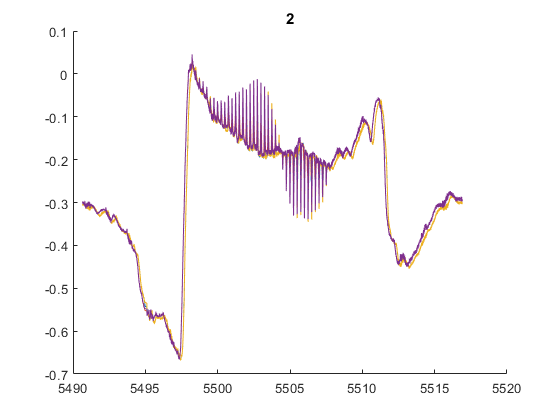

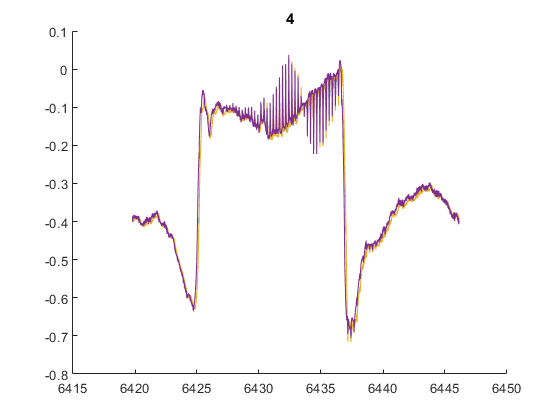

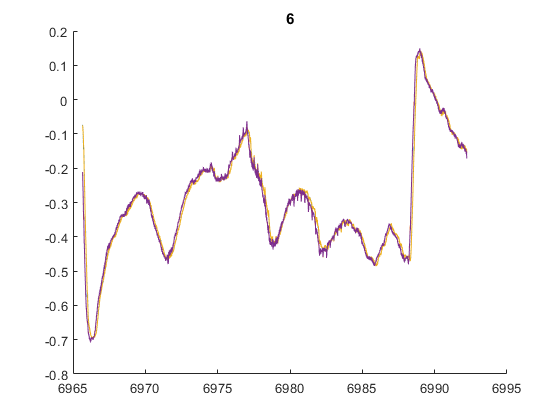

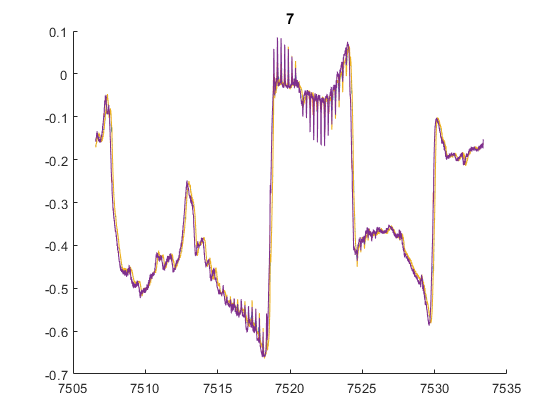

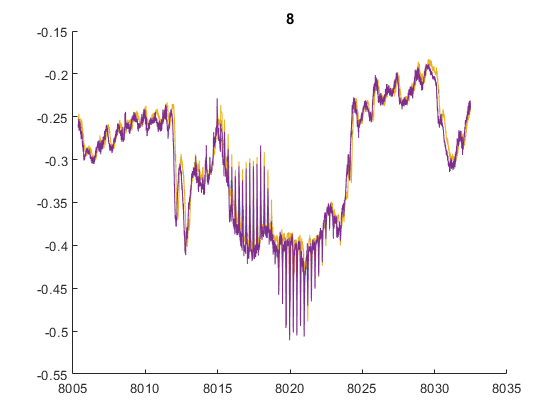

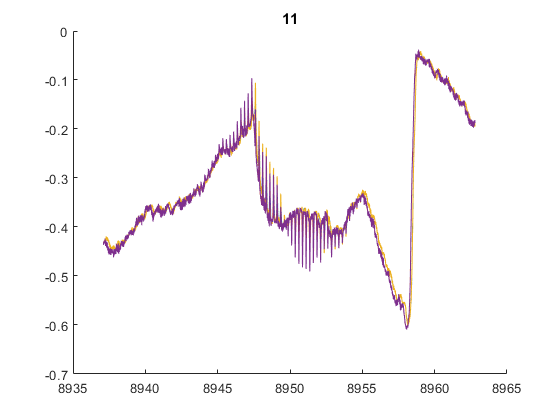

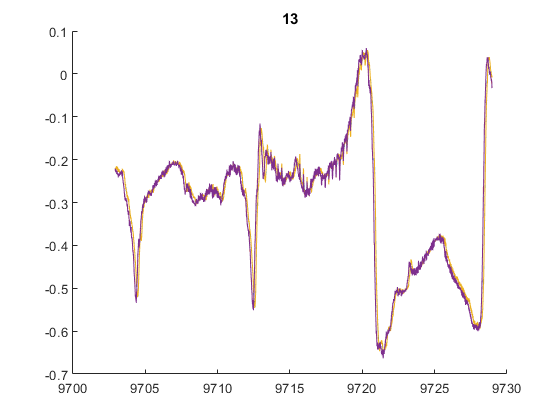

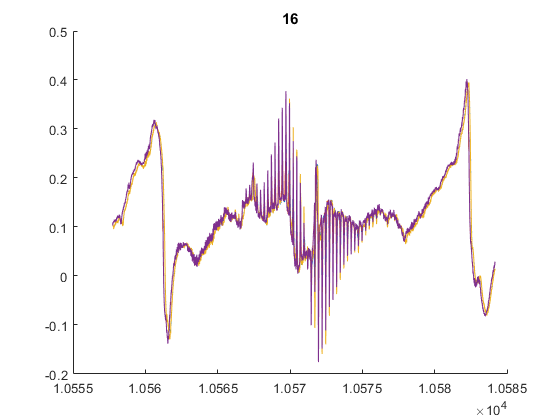

%% 取出AGM磁力區間
close all;
plus=400*25;  %設區間為25秒
agm=[2 4 6 7 8 11 13 16 18 20 24 36];  %5 25
% agm=[3 5 7 11 13 17 19 21 24 27 29 31 33 35];  %5 26
axi=1;
waveN=16; %計算的波數 16(25)
% waveN=19; %計算的波數  19(26)
n=12; %取的startn
startn=[];
startn2=[];
startn(waveN,k)=0;

fs=400; %frequency rate
fc = 7; %for startn finding
fc = 9; %for find peak difference fly
% fc = 90; %for find peak difference fly
[b,a] = butter(2,fc/(fs/2),'low'); % Butterworth filter of order 6
sm=filtfilt(b, a, m);
sm2=filtfilt(b, a, m2);
for i=1:k
    figure(i)
    title(agm(i))
    hold on    
    
%     plot(m((tickson(i)-plus/2):(tickson(i)+plus/2),axi))      %% m
%                                                                                m2
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.33)   %25
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.9)   %26
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*1+0.28)   %25   %校正後兩磁力儀方向一樣?
%     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*1)   %26   %校正後兩磁力儀方向一樣?
    %     plot(plus/2,m(tickson(i),axis),'go')
    
    %     plot(smooth(m((tickson(i)-plus/2):(tickson(i)+plus/2),axi),30)) %平滑
%     plot(sm((tickson(i)-plus/2):(tickson(i)+plus/2),axi))
    
%          plot(m((tickson(i)-plus/2):(tickson(i)+plus/2),:)) %三軸  
    %     plot(m2((tickson(i)-plus/2):(tickson(i)+plus/2),:)*-1)
    
    %     plot(plus/2,m(tickson(i),:),'ko') %定位點
%     plot(plus/2,m(tickson(i),axi),'ko')
    
    
    
    % x axis = time
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),sm((tickson(i)-plus/2):(tickson(i)+plus/2),axi))
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),sm2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.33) %25
%     plot(t(tickson(i)-plus/2:tickson(i)+plus/2),sm2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.9) %26
    
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),m((tickson(i)-plus/2):(tickson(i)+plus/2),axi))
    plot(t(tickson(i)-plus/2:tickson(i)+plus/2),m2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.33) %25
%     plot(t(tickson(i)-plus/2:tickson(i)+plus/2),sm2((tickson(i)-plus/2):(tickson(i)+plus/2),axi)*-1-0.9) %26
    
    
    %%startn finding
%     ff=-2;
%     testdata=sm((tickson(i)-plus/2*0.3):(tickson(i)+plus/2*0.3),axi); % 用來判斷的數據
%     IndMin=find(diff(sign(diff(testdata)))>0)+ff;  %獲得局部最小值的位置(可微調位置
%     IndMax=find(diff(sign(diff(testdata)))<0)+ff;  %獲得局部最大值的位置
%     
%     IndMin(waveN+1:size(IndMin))=[]; % 使同長度
%     IndMax(waveN+1:size(IndMax))=[];
%     
%        
%     for j=1:waveN
%         what=tickson(i)-plus/2*0.3+IndMin(j);
%         what2=what-tickson(i)+plus/2;
%         startn(j,i)=what2;
%         startn2(i)=startn(n,i);
%         
%         plot(startn(j,i),m(what,axi),'r^') % 標示在原數據
%         %     plot(IndMin(j)+plus/2-plus/2*0.3,m(tickson(i)-plus/2*0.3+IndMin(j),axi),'r^') % 標示在原數據
%         plot(IndMax(j)+plus/2-plus/2*0.3,m(tickson(i)-plus/2*0.3+IndMax(j),axi),'k*')
%     end
%     plot(startn2(i),m(startn2(i)+tickson(i)-plus/2,axi),'ko') % 標示在原數據
%     
%     ylabel('Gauss')
%     hold off
end

% startn2=startn2';
